# **OPTIMIZACIÓN CON ALGORITMOS GENÉTICOS - “SISTEMA DE ECUACIONES DE 3X3”**

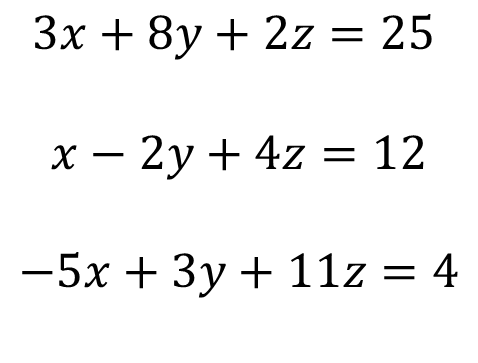

## **Inicialización de Variables**

clc
close all
clear
warning('off');
sistemaEcuaciones = [ 3 8 2 25;
                      1 -2 4 12;
                     -5 3 11 4]

sistemaEcuaciones =      3     8     2    25
     1    -2     4    12
    -5     3    11     4


## **Configuración de los aspectos generales del Algoritmo Genético**

**Método de optimización**

Se establece los algoritmos genéticos como método de optimización

options = optimoptions('ga');

**Configuración de población genética **

options = optimoptions(options,'PopulationSize' ,30);
options = optimoptions(options,'PopulationType' ,'doubleVector');
options = optimoptions(options,'PopInitRange' ,[-10 -10 -10; 10 10 10]);
options = optimoptions(options, 'CreationFcn',@gacreationuniform);

**Configuración de criterios de parada **

options = optimoptions(options, 'Generations', 100000);
options = optimoptions(options, 'FitnessLimit', 0.01);%->10%

**Criterios de parada por estancamiento**

`'TolFun'``-El algoritmo se detiene si, el cambio relativo promedio en el `

`mejor valor de la función de aptitud no es significativo.`

options =  optimoptions(options,'TolFun', 1e-6);

`'StallTimeLimit'``-El algoritmo se detiene si no hay mejora en la función`

`objetivo el tiempo establecido`

options =  optimoptions(options,'StallTimeLimit', 1000);

`'StallGenLimit'``-Limite de generaciones de estancamiento`

options =  optimoptions(options,'StallGenLimit', 1000);

## **Configuración de los Operadores Genéticos**

**Elitismo**

options = optimoptions(options, 'EliteCount', 2);

**Operador de selección**

options = optimoptions(options, 'SelectionFcn',@selectiontournament);

**Cruce**

options = optimoptions(options, 'CrossoverFcn',@crossoversinglepoint);%crossoverintermediate
options = optimoptions(options, 'CrossoverFraction', 0.9);

**Mutación**

options = optimoptions(options, 'MutationFcn',{@mutationuniform, 0.4});

## Configuración de la representación de los resultados

options = optimoptions(options, 'Display', 'off');       %Se bloquea cualquie display
options = optimoptions(options, 'PlotInterval', 10); 

Plot de mejor fitness  vs fitness promedio cada generación

options = optimoptions(options,'PlotFcns',@gaplotbestf);  

## Ejecución del Algoritmo

Ejecucion de la función "ga"

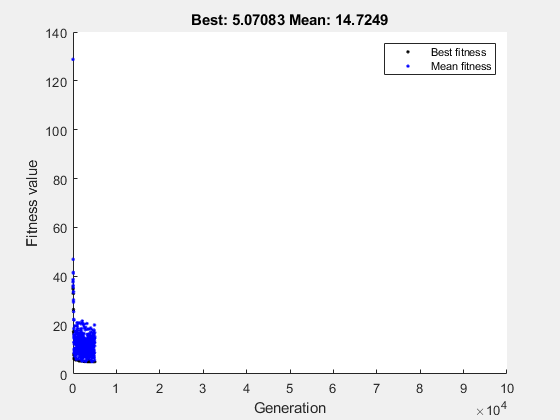

[best_genotype,best_fit]=ga(@fitness,3,options);

## Display de mejor genotipo y su fitness

disp('');
disp('Mejor Genotipo: ');

Mejor Genotipo: 


disp(best_genotype);

    5.7822    0.2256    2.9291



disp('Fitness: ');

Fitness: 


disp(best_fit);

    5.0708



## Representación de Fenotipo

Fenotipo=table(sistemaEcuaciones(:,1),best_genotype(1)*[1;1;1],...
               sistemaEcuaciones(:,2),best_genotype(2)*[1;1;1],...
               sistemaEcuaciones(:,3),best_genotype(3)*[1;1;1],...
               sistemaEcuaciones(:,4));
Fenotipo.Properties.VariableNames={'a','x','b','y','c','z','T. ind'}

Fenotipo = 3×7 table
    a       x       b        y       c       z       T. ind
    __    ______    __    _______    __    ______    ______

     3    5.7822     8    0.22557     2    2.9291      25  
     1    5.7822    -2    0.22557     4    2.9291      12  
    -5    5.7822     3    0.22557    11    2.9291       4  
